# DSP experiment 1

## Q1:x(n) = e^(( − 0 . 2 + j0 . 4)^n) ,− 10 ≤ n ≤ 10

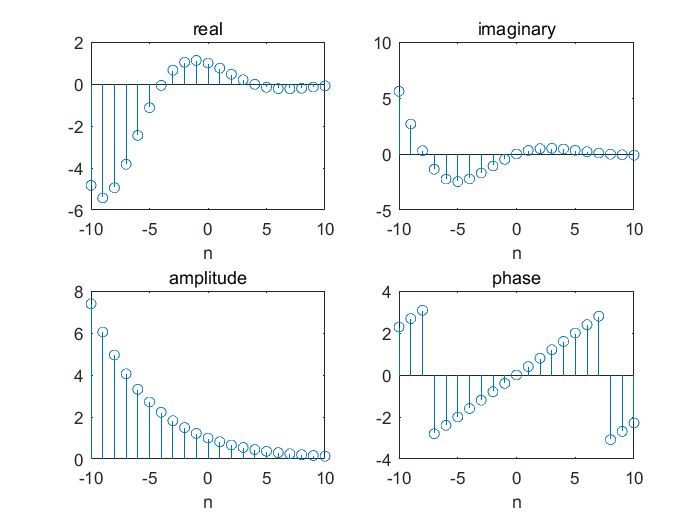

figure(1);
n=-10:10;
x=exp((-0.2+1i*0.4).*n);
subplot(2,2,1),stem(n,real(x)),title('real'),xlabel('n');
subplot(2,2,2),stem(n,imag(x)),title('imaginary'),xlabel('n');
subplot(2,2,3),stem(n,abs(x)),title('amplitude'),xlabel('n');
subplot(2,2,4),stem(n,angle(x)),title('phase'),xlabel('n');

## Q2:x(n) ={ 1 , 2 , 3 , 4 , 5 }, 0 ≤ n ≤ 4

##     h(n) = {1 ,− 2 , 1 , 3} , 0 ≤ n ≤ 3

##     h(n) = x(n) * h(n)

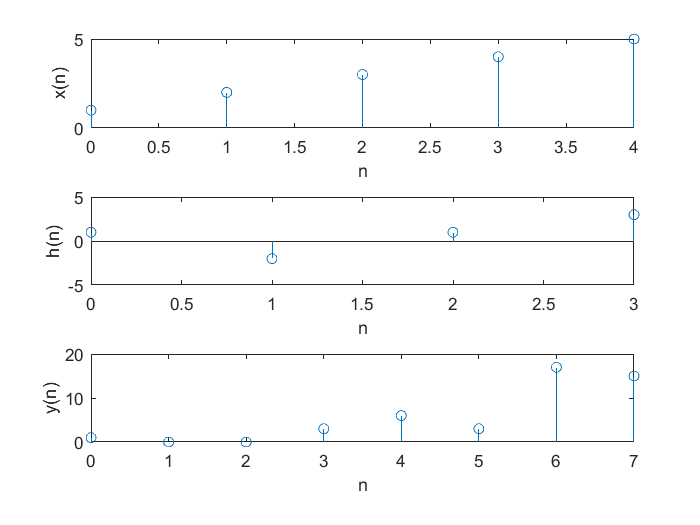

figure(2);
nx=0:4;
nh=0:3;  
x=1:5;
h=[1,-2,1,3];
y=conv(x,h);
ny=0:(length(y)-1);
subplot(3,1,1),stem(nx,x),xlabel('n'),ylabel('x(n)');
subplot(3,1,2),stem(nh,h),xlabel('n'),ylabel('h(n)');
subplot(3,1,3),stem(ny,y),xlabel('n'),ylabel('y(n)');

## Q3:y(n) − y(n − 1) + 0 . 9 y(n − 2) = x(n)

##     (1)impulse response

##     (2)unit step response

##     (3)stability

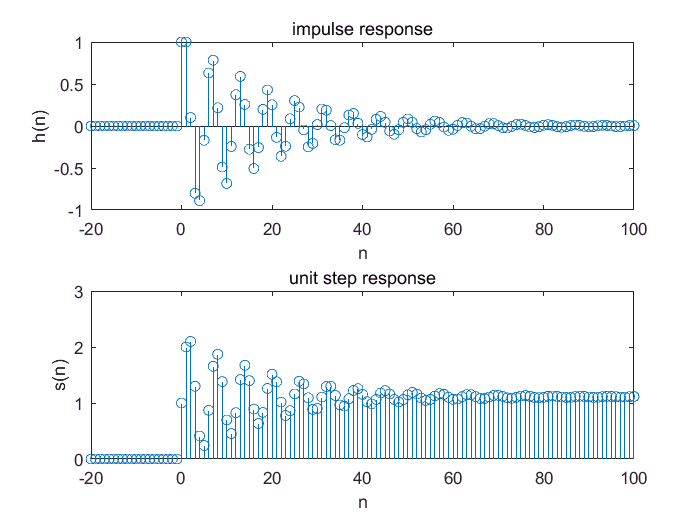

figure(3);
b=1;
a=[1,-1,0.9];
x=impseq(0,-20,100);
n=-20:100;
% y=(b/a)x
h=filter(b,a,x);
subplot(2,1,1),stem(n,h),title('impulse response'),xlabel('n'),ylabel('h(n)');

x=stepseq(0,-20,100);
s=filter(b,a,x);
subplot(2,1,2),stem(n,s),title('unit step response'),xlabel('n'),ylabel('s(n)');

z=roots(a);
magz=abs(z)

magz =     0.9487
    0.9487



if(magz(:)<1)
    fprintf('System is stable!');
end

System is stable!

Q4:(DTFT) ---X(exp(jw))

     x(n)=exp(-j0.3.*pi.*n) , 0$\le$n$\le$7

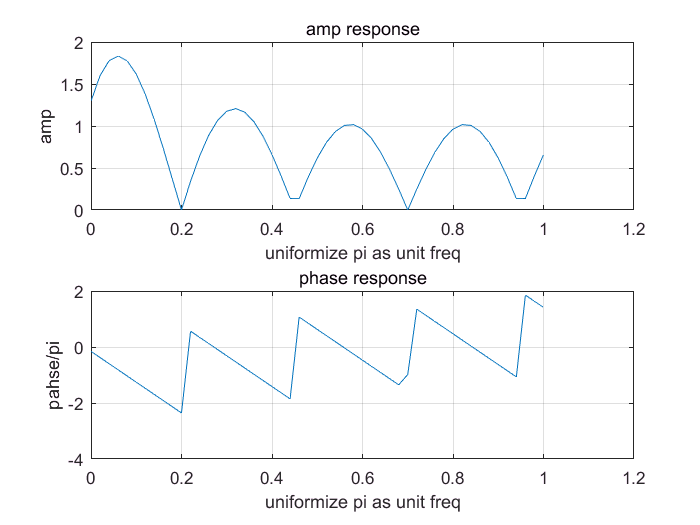

figure(4);
n=0:7;
x=exp(-1i.*0.3*pi.*n);
k=0:50;
w=2*pi/100*k;
X=x*exp(-1i.*n'*w);
subplot(2,1,1),plot(w/pi,abs(X)),title('amp response'),grid,ylabel('amp'),xlabel('uniformize pi as unit freq');
subplot(2,1,2),plot(w/pi,angle(X)),title('phase response'),grid,ylabel('pahse/pi'),xlabel('uniformize pi as unit freq');

## Q5:$\begin{array}{l}
x\left(n\right)={\left(0\ldotp 8\right)}^n u\left(n\right)\\
h\left(n\right)={\left(−0\ldotp 9\right)}^n u\left(n\right)
\end{array}$

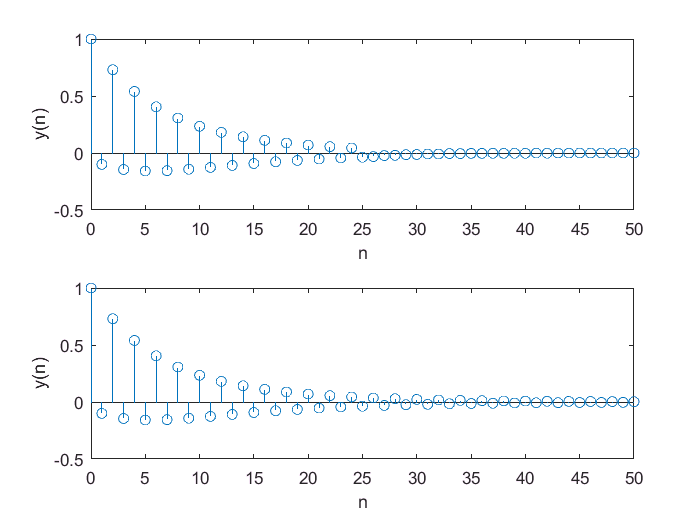

figure(5);
% convolution with conv
n=0:25;
x=0.8.^n.*stepseq(0,0,25);
h=(-0.9).^n.*stepseq(0,0,25);
y=conv(x,h);
ny=0:(length(y)-1);
subplot(211),stem(ny,y),xlabel('n'),ylabel('y(n)');

% convolution with unidimensional-d igital-filter
b=1;
a=[1 0.9];
n2=0:50;
x2=0.8.^n2.*stepseq(0,0,50);
y2=filter(b,a,x2);
subplot(2,1,2),stem(n2,y2),xlabel('n'),ylabel('y(n)');